%Stock selection optimization algorithm in function of implied risk.

T = readtable("purchasewithSNPnodate.xlsx")

T = 1006×4 table
     VALE     CLVT      WNS      VIPS 
    ______    _____    _____    ______

    6.2016    22.63    41.73    14.729
    6.0997    22.62    41.95    14.612
     6.188    22.57    48.22    15.588
    6.5005    22.11    48.15    16.095
    6.3239    22.51     48.2    15.383
    6.6296    22.89    48.34    16.914
    6.6839    24.09    49.25    16.719
    6.9692    23.35    51.74    17.188
    7.1798     22.9    54.24    17.051
    7.3632     22.4    53.45     17.11
     7.499    22.49    56.52    17.529
    7.6552    22.46     55.5    16.758
    7.6213     22.5    54.53    17.012
    7.4854     22.6    53.52    17.812
    6.9624    22.22     51.5    16.924
    7.2205     22.2    53.68    17.285


[nObservation, p] = size(T)

nObservation = 1006

p = 4

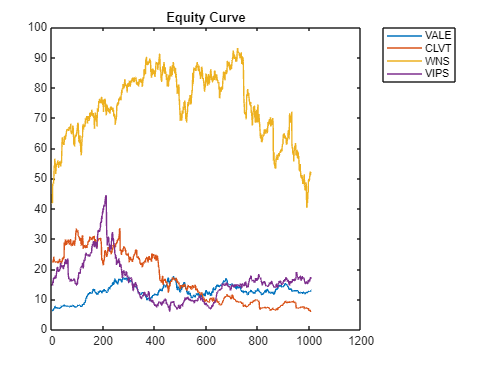

splitPoint = ceil(nObservation*0.6);
training = 1:splitPoint;
test = splitPoint+1:nObservation;
trainingNum = numel(training);

plot(T{:,1:end});
x=('Timestep');
y=('Value');
title('Equity Curve');
legend(T.Properties.VariableNames(1:end), 'Location',"bestoutside",'Interpreter','none');

k = 2;
[factorLoading,factorRetn,latent,tsq,explained,mu] = pca(T{training,(1:end)}, 'NumComponents', k);

dbstop if error

[denoisedCov,numFactorsDenoising] = covarianceDenoising(T{training,(1:end)});
disp(numFactorsDenoising)

ans =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 1.9841e-04
        AssetMean: [4×1 double]
       AssetCovar: [4×4 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 4
        AssetList: {'VALE'  'CLVT'  'WNS'  'VIPS'}
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [4×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [4×1 categorical]


clear cov

covarFactor = cov(factorRetn);

reconReturn = factorRetn*factorLoading' + mu;
unexplainedRetn = T{training,(1:end)} - reconReturn;

unexplainedCovar = diag(cov(unexplainedRetn));
D = diag(unexplainedCovar);

targetRisk = 0.05;  % Standard deviation of portfolio return
tRisk = targetRisk*targetRisk;  % Variance of portfolio return
meanStockRetn = mean(T{training,(1:end)});

optimProb = optimproblem('Description','Portfolio with factor covariance matrix','ObjectiveSense','max');
wgtAsset = optimvar('asset_weight', p, 1, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', 1);
wgtFactor = optimvar('factor_weight', k, 1, 'Type', 'continuous');

optimProb.Objective = sum(meanStockRetn'.*wgtAsset);

optimProb.Constraints.asset_factor_weight = factorLoading'*wgtAsset - wgtFactor == 0;
optimProb.Constraints.risk = wgtFactor'*covarFactor*wgtFactor + wgtAsset'*D*wgtAsset <= tRisk;
optimProb.Constraints.budget = sum(wgtAsset) == 1;

x0.asset_weight = ones(p, 1)/p;
x0.factor_weight = zeros(k, 1);
opt = optimoptions("fmincon", "Algorithm","sqp", "Display", "off", ...
    'ConstraintTolerance', 1.0e-8, 'OptimalityTolerance', 1.0e-8, 'StepTolerance', 1.0e-8);
x = solve(optimProb,x0, "Options",opt);
assetWgt1 = x.asset_weight;

%Optimal balancing based on the optimoptions algorithm >

percentage = 0.15;
AssetName = T.Properties.VariableNames(assetWgt1>=percentage)';
Weight = assetWgt1(assetWgt1>=percentage);
T1 = table(AssetName, Weight)

T1 = 2×2 table
    AssetName    Weight 
    _________    _______

    {'WNS' }     0.21825
    {'VIPS'}     0.16442
